# Image Compression Using FFT

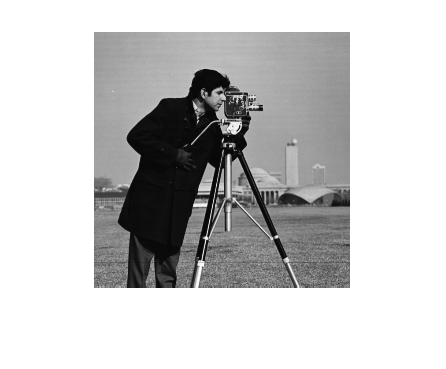

clear;clc;

img = imread('images/cameraman.tif');
% img = rgb2gray(imread('images/pout.tif'));
figure(1);
imshow(img);

## Calculate 2D FFT

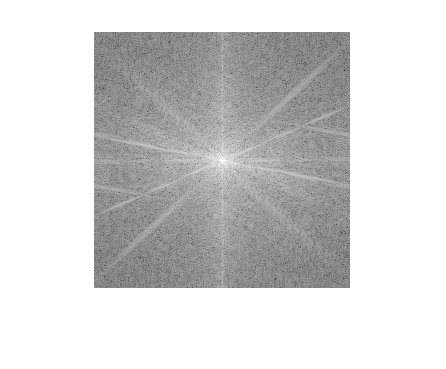

img_w = fft2(img); % get the FFT
shifted_w = fftshift(img_w);
img_freq = log(1+abs(shifted_w));
figure(2);
imshow(img_freq/(max(max(img_freq)-min(min(img_freq)))));

## Compress Freq Data

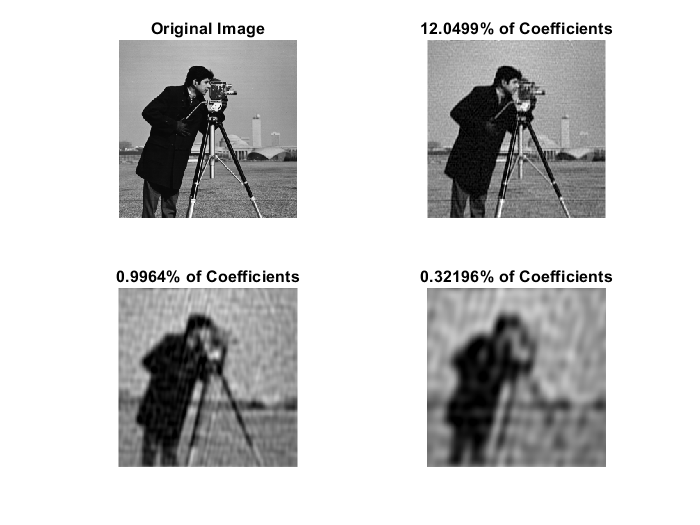

figure(3), subplot(2, 2, 1), imshow(img);
title('Original Image','FontSize',10);
drawnow;
pic_count = 2;
for thresh = [0.001 0.005 0.01] * max(max(abs(img_w)))
    ind = abs(img_w)>thresh;
    img_w_comp = img_w.*ind;    
    img_comp = uint8(ifft2(img_w_comp));
    count = sum(sum(ind));
    [nrows, ncols] = size(ind);
    percent = count*100/(nrows*ncols);
    figure(3), subplot(2, 2, pic_count), imshow(img_comp);
    title([num2str(percent) '% of Coefficients'],'FontSize',10);
    drawnow;
    pic_count = pic_count + 1;
end